# **Amar Ramdas - 4461487**

## **Exercise 1:**

P7.1. Write a program that illustrates the timescale invariance of the asset model, in the style of Figure 7.5

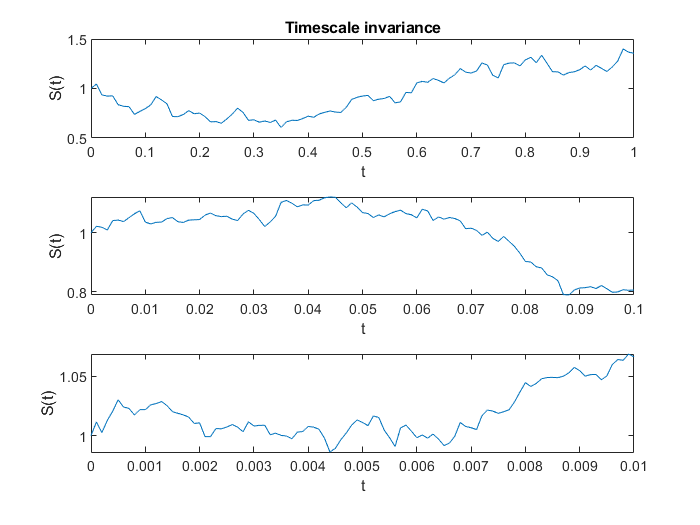

%CH07 Program for Chapter 7 % % Plot discrete sample paths
warning off;
clear all;
randn('state',100) ;
clf

%%%%%%%%% Problem parameters %%%%%%%%%%
S=1; mu=0.05; sigma = 0.5; L = 1e2; 

for i = 0:2
    T = 10^-i; 
    dt =T/L; M = 1; 

    tvals = [0:dt:T]; 
    Svals = S*cumprod(exp((mu-0.5*sigma^2)*dt + sigma*sqrt(dt)*randn(M,L)),2); 
    Svals = [S*ones(M,1) Svals]; % add initial asset price 
    
    
    h(i+1) = subplot(3,1,i+1);
        
    plot(tvals,Svals)
    xlabel('t'), ylabel('S(t)')
    
    if i==0
            title('Timescale invariance') 
    end
end 

**Exercise 2:**

Solve Exercise 8.10 from the book by Higham, page 83

For V(S,t)=S we get


$$\frac{\partial }{\partial t}S+\frac{1}{2}\sigma^2 S^2 \frac{\partial^2 }{\partial S^2 }S+\mathrm{rS}\frac{\partial }{\partial S}S-\mathrm{rS}=0$$



$$0+\;0+\textrm{rS}-\textrm{rS}=0$$


At V=S for every t, it's a derivative that always has the stock price, without actually owning the stock. 

For V(S,t)=e^rt


$$\frac{\partial }{\partial t}e^{\mathrm{rt}} +\frac{1}{2}\sigma^2 S^2 \frac{\partial^2 }{\partial S^2 }e^{\mathrm{rt}} +\textrm{rS}\frac{\partial }{\partial S}e^{\mathrm{rt}} -\textrm{r}e^{\mathrm{rt}} =0$$



$${\mathrm{re}}^{\mathrm{rt}} +\;0+0-\textrm{r}e^{\mathrm{rt}} =0$$


For this situation, the value can be replicated by just putting money on the bank, as it equals the compound rate.

**Exercise 3:**

a) generate 10 asset paths driven by geometric Brownian motion and the parameters above

studentno = 4461487;
mu = studentno;

%divide mu by 10 until mu<0.1
while mu>0.1
mu = mu / 10;
end

mu

mu = 0.0446

sigma = mu*4

sigma = 0.1785

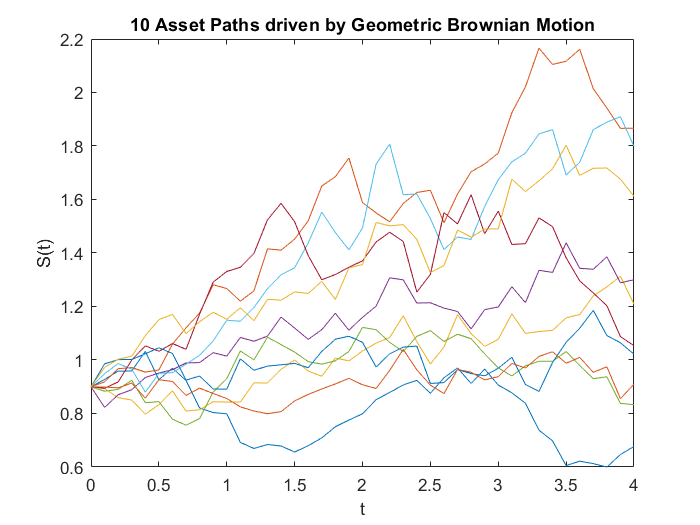

s0 = 0.9;

T=4;
dt= 10^-1;

steps = T/dt;

%using matlab geometric Brownian Motion function
obj = gbm(mu, diag(sigma), 'StartState', s0) ;
[X1,T] = obj.simulate(steps, 'DeltaTime', dt,'ntrials', 10);
X1 = squeeze(X1);
figure()
plot(T,X1)
xlim([0, 4])
xlabel('t'), ylabel('S(t)')
title('10 Asset Paths driven by Geometric Brownian Motion')

b)   Plot for these paths the "running sum of square returns". 

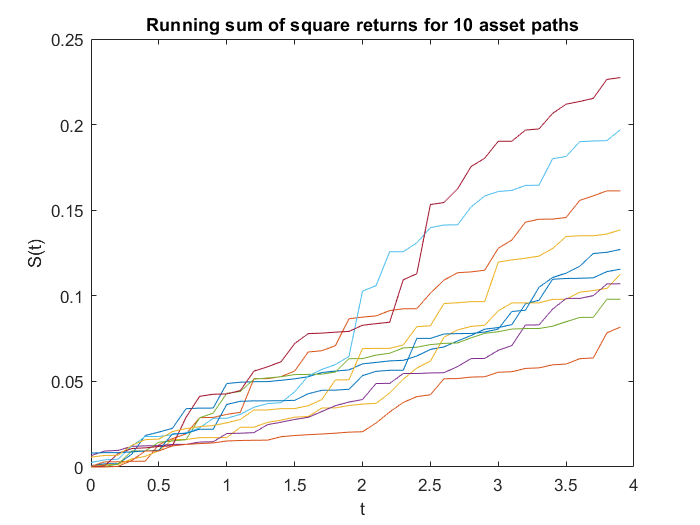

xsize = size(X1);
for k = 1: xsize(1)-1
   DX1(k,:) = (X1(k+1,:)-X1(k,:)).^2;
end

a=X1(1:end-1,:);
DX1 = DX1./a;
C1 = cumsum(DX1, 1);
plot(T(1:end-1),C1);
xlim([0, 4])
xlabel('t'), ylabel('S(t)')
title('Running sum of square returns for 10 asset paths');

Repeat this exercise with 1000 asset paths

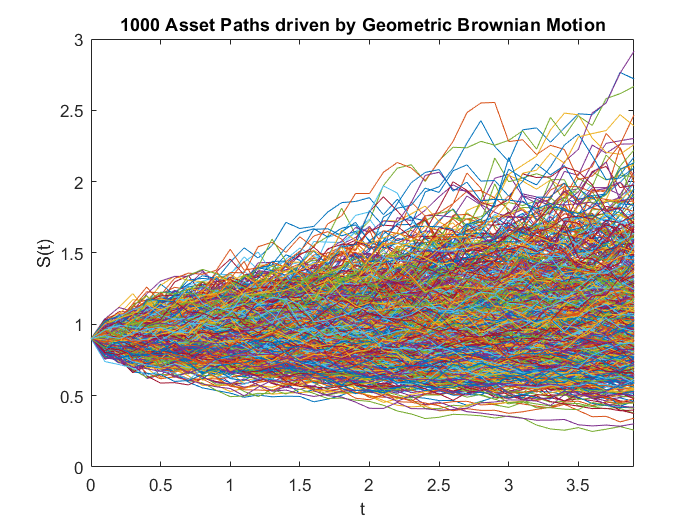

[X2,T2] = obj.simulate(steps, 'DeltaTime', dt,'ntrials', 1000);
X2 = squeeze(X2);
figure()
plot(T2,X2)
xlim([0, 4-dt])
xlabel('t'), ylabel('S(t)')
title('1000 Asset Paths driven by Geometric Brownian Motion')

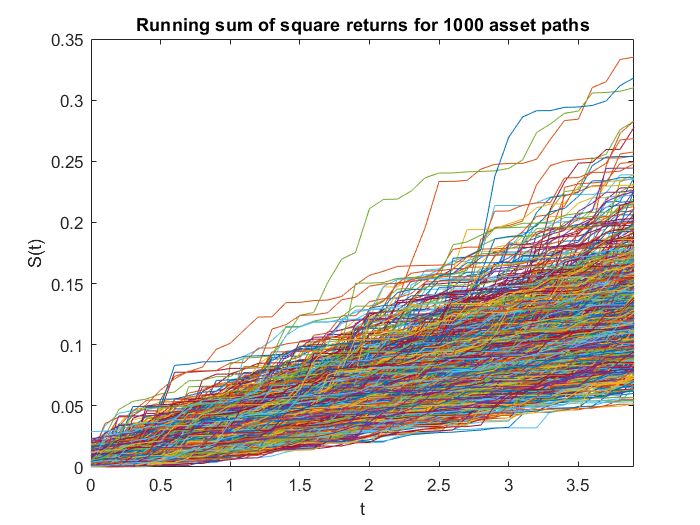

x2size = size(X2);
for l = 1: x2size(1)-1
   DX2(l,:) = (X2(l+1,:)-X2(l,:)).^2;
end

b=X2(1:end-1,:);
DX2 = DX2./b;

C2 = cumsum(DX2, 1);
plot(T2(1:end-1),C2);
xlim([0, 4-dt])
xlabel('t'), ylabel('S(t)')
title('Running sum of square returns for 1000 asset paths');

c)

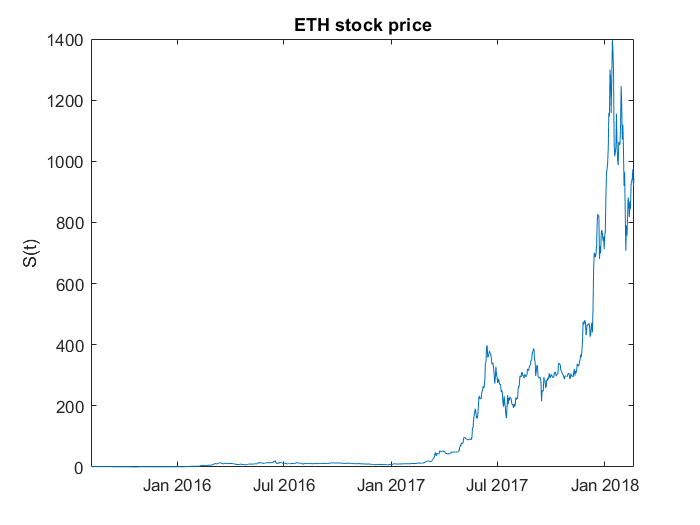

%import data for ethereum
ethFileName = 'cryptodata/ethereum_price.csv';
warning off
ethTable = readtable(ethFileName);

%select correct rows
ethDateRow = flipud(ethTable{:, 'Date'});
y = flipud(ethTable{:, 'Open'});

%do the same for eth classic
ethClassicFileName = 'cryptodata/ethereum_classic_price.csv';
ethClassicTable = readtable(ethClassicFileName);
warning on
ethClassicDateRow = flipud(ethClassicTable{:, 'Date'});
y2 = flipud(ethClassicTable{:, 'Open'});

ethsize = size(y);
ethClassicSize = size(y2);

for m = 1 : ethsize(1) - 1 
    ethChange(m) = ((y(m+1)-y(m))/y(m))^2;  
end

for n = 1: ethClassicSize(1)-1
    ethClassicChange(n) = ((y2(n+1)-y2(n))/y2(n))^2;  
end

warning off
plot(ethDateRow, y)
ylabel('S(t)')
title('ETH stock price');
xlim([ethDateRow(1), ethDateRow(end)])

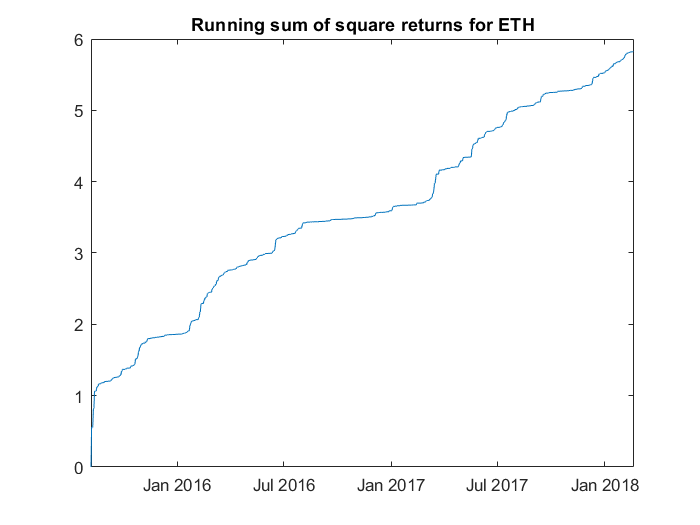

plot(ethDateRow(1:end-1), cumsum(ethChange));
title('Running sum of square returns for ETH');
xlim([ethDateRow(1), ethDateRow(end)])

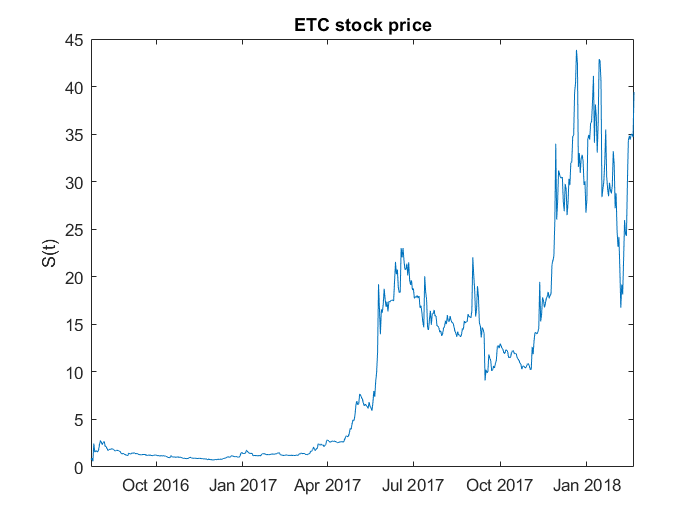


plot(ethClassicDateRow, y2)
ylabel('S(t)')
title('ETC stock price');
xlim([ethClassicDateRow(1), ethClassicDateRow(end)])

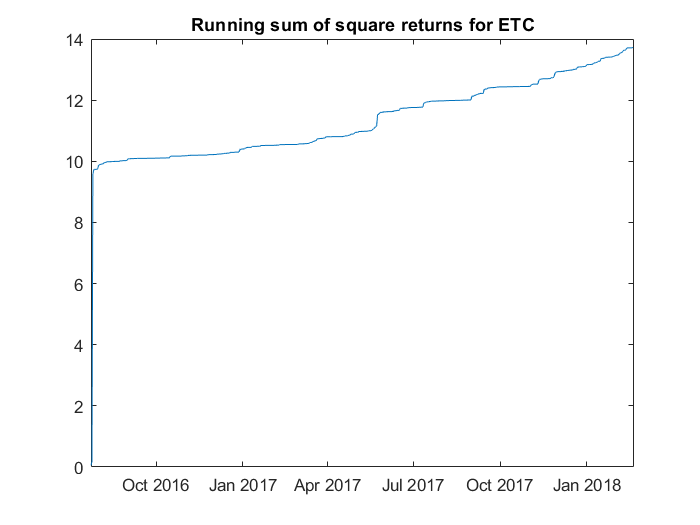

plot(ethClassicDateRow(1:end-1), cumsum(ethClassicChange));
title('Running sum of square returns for ETC');
xlim([ethClassicDateRow(1), ethClassicDateRow(end)])

%%eth classic dataset has a jump at the beginning, distorting the graph a bit